# **Week L3: Single-Carrier with Alamouti Coding**

This script implements a simplified optic fibre communications system using Alamouti coding

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using 16-QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Alamouti Coding

clearvars

% Parameters
NSymb = 300000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% FOR QAM:
% Generating random bit sequence(s)
sourceBitsQAM = randi([0 1], NSymb*4, 1); % Matrix of source bits for QAM
sourceIntsQAM = bit2int(sourceBitsQAM, 4); % Vector of source bits converted to ints
sourceSymbolsQAM = qammod(sourceIntsQAM, 16, UnitAveragePower=true) % Maps source bit vector to symbol vector

sourceSymbolsQAM =    0.9487 - 0.9487i
  -0.3162 + 0.9487i
  -0.3162 + 0.3162i
  -0.9487 + 0.3162i
  -0.3162 + 0.3162i
  -0.9487 + 0.9487i
  -0.3162 - 0.3162i
   0.9487 - 0.3162i
   0.9487 - 0.9487i
   0.9487 - 0.3162i


codedSymbolsQAM = AlamoutiCoding(sourceSymbolsQAM) % Encodes symbols using Alamouti coding

codedSymbolsQAM =    0.9487 - 0.9487i  -0.3162 + 0.9487i
   0.3162 + 0.9487i   0.9487 + 0.9487i
  -0.3162 + 0.3162i  -0.9487 + 0.3162i
   0.9487 + 0.3162i  -0.3162 - 0.3162i
  -0.3162 + 0.3162i  -0.9487 + 0.9487i
   0.9487 + 0.9487i  -0.3162 - 0.3162i
  -0.3162 - 0.3162i   0.9487 - 0.3162i
  -0.9487 - 0.3162i  -0.3162 + 0.3162i
   0.9487 - 0.9487i   0.9487 - 0.3162i
  -0.9487 - 0.3162i   0.9487 + 0.9487i



vI_QAM = real(codedSymbolsQAM);
vQ_QAM = imag(codedSymbolsQAM);

vI_QAM_upsampled = repelem(vI_QAM, SpS, 1); % Upsampling according to SpS
vQ_QAM_upsampled = repelem(vQ_QAM, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QAM_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QAM_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QAM")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

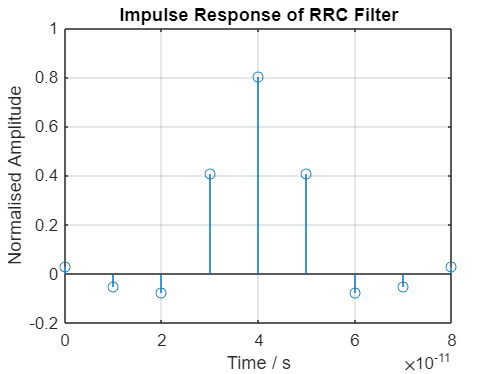

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

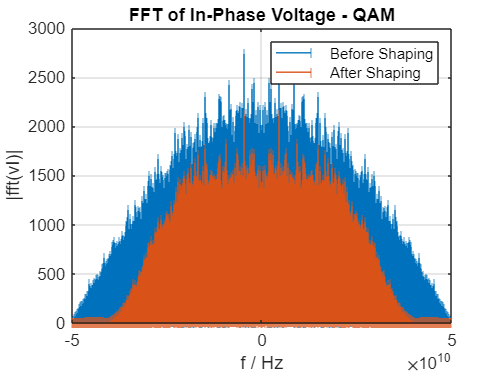


% ---------------------------------------------------------------------------

% FOR QAM:
% Using RRC filter to shape vI and vQ

vI_QAM_shaped = upfirdn(vI_QAM, filterResponse, SpS, 1); vQ_QAM_shaped = upfirdn(vQ_QAM, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QAM = fftshift(fft(vI_QAM_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QAM_shaped = fftshift(fft(vI_QAM_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QAM), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QAM_shaped), "|");
title("FFT of In-Phase Voltage - QAM");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QAM");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### IQ Modulation

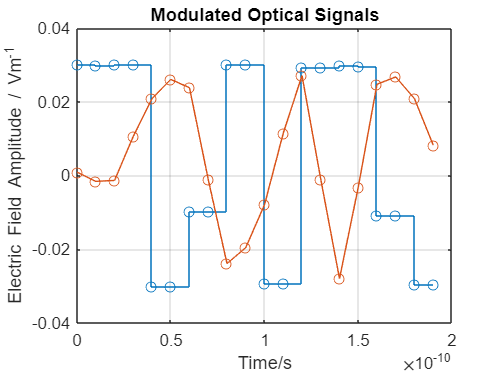

% Initialising laser parameters
lineWidth = 1e5;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a continuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
% plot(t(1:20), real(laserE(1:20)), "o-");
% title("Laser Output as a Continous Wave");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}");
% grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigQAM = (vI_QAM_upsampled+1i*vQ_QAM_upsampled).*laserE;
modOpticSigQAM_shaped = (vI_QAM_shaped+1i*vQ_QAM_shaped).*laserE_shaped;

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), "o-");
hold on
plot(t(1:10*SpS), real(modOpticSigQAM_shaped(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
grid on
hold off

## Optical Channel

% Inserting CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

channelOutQAM_CD = CDInsertion(modOpticSigQAM, SpS, Rs, D, CLambda, linkLength, 2); 
channelOutQAM_shaped_CD = CDInsertion(modOpticSigQAM_shaped, SpS, Rs, D, CLambda, linkLength, 2); 

% Inserting rotations
thetaArr = [30:10:80];
modOpticSigQAM_rot = zeros(size(modOpticSigQAM,1), size(modOpticSigQAM,2), length(thetaArr));
for i=1:size(thetaArr,2)
    modOpticSigQAM_rot(:,:,i) = PolRotate(modOpticSigQAM, thetaArr(i), 0);
end


% Debugging addition of CD through immediate CD compensation

% debugCDC = OverlapSaveCDC(channelOutQAM_CD(:,1),D,linkLength,CLambda,Rs,1,SpS,2^9,50);
% 
% channelOutQAM_shaped_CD_filtered = upfirdn(channelOutQAM_shaped_CD(:,1), filterResponse, 1, SpS);
% channelOutQAM_shaped_CD_filtered = channelOutQAM_shaped_CD_filtered(filterSpan+1:end-filterSpan);
% debugCDC_shaped = OverlapSaveCDC(channelOutQAM_shaped_CD(:,1)/sqrt(laserPw_Lin),D,linkLength,CLambda,Rs,1,SpS,2^9,75);

% Evaluating BER when CDC is applied after filtering
% debugCDC_shaped_filtered = debugCDC_shaped;
% debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% 
% debugCDC_shaped_filtered_Ints = qamdemod(debugCDC_shaped_filtered, 16, UnitAveragePower=true);
% debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 4);
% [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQAM)

% Evaluating BER when CDC is applied before filtering
% debugCDC_shaped_filtered = upfirdn(debugCDC_shaped, filterResponse, 1, SpS);
% debugCDC_shaped_filtered = debugCDC_shaped_filtered(filterSpan+1:end-filterSpan);
% debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% 
% debugCDC_shaped_filtered_Ints = qamdemod(debugCDC_shaped_filtered, 16, UnitAveragePower=true);
% debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 4);
% [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQAM)
% 
% % Visualising symbol distributions
% plot(channelOutQAM_CD(:,1), ".");
% hold on
% plot(debugCDC, ".");
% plot(modOpticSigQAM(:,1), '+');
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off
% 
% plot(channelOutQAM_shaped_CD(:,1)/sqrt(laserPw_Lin), ".");
% hold on
% plot(debugCDC_shaped_filtered, ".");
% plot(modOpticSigQAM_shaped(:,1)/sqrt(laserPw_Lin), '.');
% title("Distorted Symbol Distribution with CD - Shaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off

### Adding AWGN

% Adding AWGN to the voltage waveforms before pulse shaping

SNRb_dB = [0 5 10]; % SNR per bit in dB
SNRb_Lin = 10.^(SNRb_dB/10); % SNR per bit 

powerPerSymb = mean(voltageLevelsQAM.^2);
powerPerBit= powerPerSymb/2;

SNRb_Lin = 10.^(SNRb_dB/10); % linear SNR per symbol
AWGN_StdDev = sqrt(powerPerSymb./SNRb_Lin); % AWGN Standard deviation

channelOutQAM_AWGN = zeros(size(modOpticSigQAM,1), size(modOpticSigQAM,2), length(SNRb_dB));
channelOutQAM_AWGN_CD = zeros(size(channelOutQAM_CD,1), size(channelOutQAM_CD,2), length(SNRb_dB));
channelOutQAM_shaped_AWGN = zeros(size(modOpticSigQAM_shaped,1), size(modOpticSigQAM_shaped,2), length(SNRb_dB));
channelOutQAM_shaped_AWGN_CD = zeros(size(channelOutQAM_shaped_CD,1), size(channelOutQAM_shaped_CD,2), length(SNRb_dB));

noisePw = zeros(1,length(SNRb_dB)); noisePw_shaped = zeros(1,length(SNRb_dB));
noisePw_CD = zeros(1,length(SNRb_dB)); noisePw_shaped_CD = zeros(1,length(SNRb_dB));

for i=1:length(SNRb_dB)
%      [channelOutQAM_AWGN(:,:,i), noisePw(1,i)] = awgn(modOpticSigQAM, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=4), 'measured');
%      [channelOutQAM_AWGN_CD(:,:,i), noisePw_CD(1,i)] = awgn(channelOutQAM_CD, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=4), 'measured');
%      [channelOutQAM_shaped_AWGN(:,:,i), noisePw_shaped(1,i)] = awgn(modOpticSigQAM_shaped, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=4), 'measured');
     [channelOutQAM_shaped_AWGN_CD(:,:,i), noisePw_shaped_CD(1,i)] = awgn(channelOutQAM_shaped_CD, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=4), 'measured');
end

% Adding polarization rotations
theta = 45;
for i=1:length(SNRb_dB)
%     channelOutQAM_AWGN_CD(:,:,i) = PolRotate(channelOutQAM_AWGN_CD(:,:,i), thetaArr, 0);
    channelOutQAM_shaped_AWGN_CD(:,:,i) = PolRotate(channelOutQAM_shaped_AWGN_CD(:,:,i), theta, 0);
end

% Debugging AWGN addition

% sigPw = var(modOpticSigQAM(:,1),0,1)
% sigPw_shaped = var(modOpticSigQAM_shaped(:,1),0,1)
% 
% noisePw
% noisePw_shaped
% debugSNR = 10*log10(sigPw./noisePw) - 10*log10(2)
% debugSNR_shaped = 10*log10(sigPw_shaped./noisePw_shaped) - 10*log10(2)
% 
% sigPw_CD = var(channelOutQAM_CD(:,1),0,1)
% sigPw_shaped_CD = var(channelOutQAM_shaped_CD(:,1),0,1)
% 
% noisePw_CD
% noisePw_shaped_CD
% debugSNR_CD = 10*log10(sigPw_CD./noisePw_CD) - 10*log10(2)
% debugSNR_shaped_CD = 10*log10(sigPw_shaped./noisePw_shaped_CD) - 10*log10(2)
% 
% %--------------------------------------------------------------------------------
% 
% % Visualising in-phase voltage with and without noise
% stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), '-o');
% hold on
% stairs(t(1:10*SpS), real(channelOutQAM_AWGN(1:10*SpS,1)), '-o');
% title("In-Phase Electric Field");
% xlabel("Time / s");
% ylabel("Electric Field / Vm^{-1}");
% legend("Without AWGN", "With AWGN");
% grid on
% hold off
% 
% % Visualising Symbol Distribution
% plot(channelOutQAM_AWGN(:,1,1), '.');
% hold on
% plot(channelOutQAM_AWGN(:,1,end), '.');
% plot(sourceSymbolsQAM(:,1)*sqrt(laserPw_Lin), '+', Linewidth=2);
% title("Symbol Distribution with AWGN");
% xlabel("real");
% ylabel("Imaginary")
% grid on
% hold off
% 
% BERQAM_AWGN_test = zeros(1,length(SNRb_dB)); BERQAM_shaped_AWGN_test = zeros(1,length(SNRb_dB));
% channelOutQAM_test = channelOutQAM_AWGN(1:SpS:end,1,:); channelOutQAM_test(2:2:end,1,:) = -1*conj(channelOutQAM_test(2:2:end,1,:));
% 
% channelOutQAM_reshaped = reshape(channelOutQAM_shaped_AWGN(:,1,:),samples,size(channelOutQAM_shaped_AWGN,3),1);
% channelOutQAM_shaped_test = upfirdn(channelOutQAM_reshaped/sqrt(laserPw_Lin), filterResponse, 1, SpS); 
% channelOutQAM_shaped_test = channelOutQAM_shaped_test(filterSpan+1 : end-filterSpan,:,:);
% channelOutQAM_shaped_test(2:2:end,:) = -1*conj(channelOutQAM_shaped_test(2:2:end,:));
% 
% for i=1:length(SNRb_dB)
%     IntsQAM_AWGN_test = qamdemod(channelOutQAM_test(:,1,i)/sqrt(laserPw_Lin), 16, UnitAveragePower=true);
%     BitsQAM_AWGN_test = int2bit(IntsQAM_AWGN_test, 4);
%     [~, BERQAM_AWGN_test(1,i)] = biterr(BitsQAM_AWGN_test, sourceBitsQAM);
% 
%     IntsQAM_shaped_AWGN_test = qamdemod(channelOutQAM_shaped_test(:,i,1), 16, UnitAveragePower=true);
%     BitsQAM_shaped_AWGN_test = int2bit(IntsQAM_shaped_AWGN_test, 4);
%     [~, BERQAM_shaped_AWGN_test(1,i)] = biterr(BitsQAM_shaped_AWGN_test, sourceBitsQAM);
% end
% 
% semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
% hold on
% semilogy(SNRb_dB, BERQAM_AWGN_test', '*');
% semilogy(SNRb_dB, BERQAM_shaped_AWGN_test', '*');
% title("BER vs. SNR for QAM");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

### Optical Front-End

% Generating Local optical signal for coherent detection
% carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
% freq_offset = 0; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % LO signal with non-zero linewidth for shaped signals
% Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
% Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "-o");
% hold on
% plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% legend("Ideal", "Frequency-Shifted")
% hold off
% grid on

% Visualising FFTs of original and frequency shifted LO laser signal
% fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
% fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
% freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

% stem(freqArr_Elo, abs(fft_Elo), "|");
% hold on
% stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
% title("FFT of LO Signals");
% xlabel("f / Hz");
% ylabel("|fft(Elo)|");
% legend("Matched signal", "Frequency-shifted signal");
% hold off
% grid on

% ---------------------------------------------------------------------------------------

% Generating output from optical front-end
eta_ph = 1; % Responsivity of photodetectors

% WITHOUT AWGN
OpticFEOutQAM = OpticalFrontEnd(modOpticSigQAM, [Elo Elo], eta_ph, 2); % Unshaped
OpticFEOutQAM_CD = OpticalFrontEnd(channelOutQAM_CD, [Elo Elo], eta_ph, 2); % Unshaped + CD
OpticFEOutQAM_shaped = OpticalFrontEnd(modOpticSigQAM_shaped, [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped
OpticFEOutQAM_shaped_CD = OpticalFrontEnd(channelOutQAM_shaped_CD, [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped + CD

% Unshaped + rotation
OpticFEOutQAM_rot = zeros(size(modOpticSigQAM_rot,1), 2*size(modOpticSigQAM_rot,2),size(modOpticSigQAM_rot,3));
for i=1:size(modOpticSigQAM_rot,3)
    OpticFEOutQAM_rot(:,:,i) = OpticalFrontEnd(modOpticSigQAM_rot(:,:,i), [Elo Elo], eta_ph, 2);
end

% WITH AWGN
% OpticFEOutQAM_AWGN = zeros(size(channelOutQAM_AWGN,1), 4, length(SNRb_dB));
% OpticFEOutQAM_AWGN_CD = zeros(size(channelOutQAM_AWGN_CD,1), 4, length(SNRb_dB));
% OpticFEOutQAM_shaped_AWGN = zeros(size(channelOutQAM_shaped_AWGN,1), 4, length(SNRb_dB));
OpticFEOutQAM_shaped_AWGN_CD = zeros(size(channelOutQAM_shaped_AWGN_CD,1), 4, length(SNRb_dB));

for i=1:length(SNRb_dB)
%     OpticFEOutQAM_AWGN(:,:,i) = OpticalFrontEnd(channelOutQAM_AWGN(:,:,i), [Elo Elo], eta_ph, 2); % Unshaped + AWGN
%     OpticFEOutQAM_AWGN_CD(:,:,i) = OpticalFrontEnd(channelOutQAM_AWGN_CD(:,:,i), [Elo Elo], eta_ph, 2); % Unshaped + AWGN + CD
%     OpticFEOutQAM_shaped_AWGN(:,:,i) = OpticalFrontEnd(channelOutQAM_shaped_AWGN(:,:,i), [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped + AWGN
    OpticFEOutQAM_shaped_AWGN_CD(:,:,i) = OpticalFrontEnd(channelOutQAM_shaped_AWGN_CD(:,:,i), [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped + AWGN + CD
end

% ---------------------------------------------------------------------------------------

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% QAM
% WITHOUT AWGN
OpticFEOutQAM_I = TIA_Gain*OpticFEOutQAM(:,1:2:end); OpticFEOutQAM_Q = TIA_Gain*OpticFEOutQAM(:,2:2:end); % Unshaped 
OpticFEOutQAM_CD_I = TIA_Gain*OpticFEOutQAM_CD(:,1:2:end); OpticFEOutQAM_CD_Q = TIA_Gain*OpticFEOutQAM_CD(:,2:2:end); % Unshaped + CD
OpticFEOutQAM_rot_I = TIA_Gain*OpticFEOutQAM_rot(:,1:2:end,:); OpticFEOutQAM_rot_Q = TIA_Gain*OpticFEOutQAM_rot(:,2:2:end,:); % Unshaped + rotated
OpticFEOutQAM_shaped_I = TIA_Gain*OpticFEOutQAM_shaped(:,1:2:end); OpticFEOutQAM_shaped_Q = TIA_Gain*OpticFEOutQAM_shaped(:,2:2:end); % Shaped 
OpticFEOutQAM_shaped_CD_I = TIA_Gain*OpticFEOutQAM_shaped_CD(:,1:2:end); OpticFEOutQAM_shaped_CD_Q = TIA_Gain*OpticFEOutQAM_shaped_CD(:,2:2:end); % Shaped + CD

% WITH AWGN
% OpticFEOutQAM_AWGN_I = TIA_Gain*OpticFEOutQAM_AWGN(:,1:2:end,:); OpticFEOutQAM_AWGN_Q = TIA_Gain*OpticFEOutQAM_AWGN(:,2:2:end,:); % Unshaped + AWGN
% OpticFEOutQAM_AWGN_CD_I = TIA_Gain*OpticFEOutQAM_AWGN_CD(:,1:2:end,:); OpticFEOutQAM_AWGN_CD_Q = TIA_Gain*OpticFEOutQAM_AWGN_CD(:,2:2:end,:); % Unshaped + AWGN + CD
% OpticFEOutQAM_shaped_AWGN_I = TIA_Gain*OpticFEOutQAM_shaped_AWGN(:,1:2:end,:); OpticFEOutQAM_shaped_AWGN_Q = TIA_Gain*OpticFEOutQAM_shaped_AWGN(:,2:2:end,:); % Shaped + AWGN
OpticFEOutQAM_shaped_AWGN_CD_I = TIA_Gain*OpticFEOutQAM_shaped_AWGN_CD(:,1:2:end,:); OpticFEOutQAM_shaped_AWGN_CD_Q = TIA_Gain*OpticFEOutQAM_shaped_AWGN_CD(:,2:2:end,:); % Shaped + AWGN + CD

% Debuggin optical front-end
% plot(t(1:10*SpS), real(channelOutQAM_shaped_AWGN_CD(1:10*SpS,1,1)), "-o")
% hold on
% plot(t(1:10*SpS), 100*OpticFEOutQAM_shaped_AWGN_CD_I(1:10*SpS,1,1), "-o")
% title("Comparison of Channel Output with Optic-Front End")
% xlabel("Time / s")
% ylabel("Value")
% legend("Channel Output", "Optic Front-End Output")
% hold off
% grid on

## DSP

### Scaling 

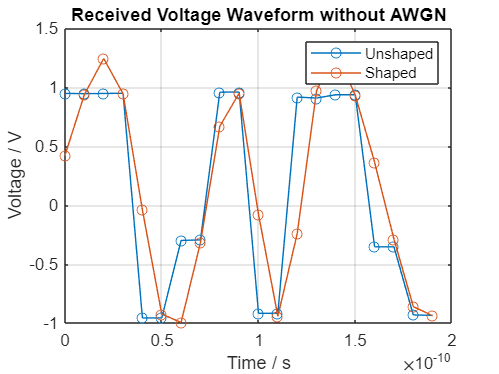

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor=1;
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag;

% Cancelling the scaling factor and downsampling:
% QAM
% WITHOUT AWGN
voltageQAM_I = OpticFEOutQAM_I/scaleFactor; voltageQAM_Q = OpticFEOutQAM_Q/scaleFactor; % Unshaped 
voltageQAM_CD_I = OpticFEOutQAM_CD_I/scaleFactor; voltageQAM_CD_Q = OpticFEOutQAM_CD_Q/scaleFactor; % Unshaped + CD
voltageQAM_rot_I = OpticFEOutQAM_rot_I/scaleFactor; voltageQAM_rot_Q = OpticFEOutQAM_rot_Q/scaleFactor; % Unshaped + rot

voltageQAM_shaped_I = upfirdn(OpticFEOutQAM_shaped_I/scaleFactor, filterResponse, 1, 1); voltageQAM_shaped_I = voltageQAM_shaped_I(filterSpan*SpS:end - filterSpan*SpS,:); % Shaped 
voltageQAM_shaped_Q = upfirdn(OpticFEOutQAM_shaped_Q/scaleFactor, filterResponse, 1, 1); voltageQAM_shaped_Q = voltageQAM_shaped_Q(filterSpan*SpS:end - filterSpan*SpS,:); % Shaped 

plot(t(1:SpS*10), voltageQAM_I(1:SpS*10,1), "-o");
hold on
plot(t(1:SpS*10), voltageQAM_shaped_I(1:SpS*10,1), "-o");
title("Received Voltage Waveform without AWGN");
xlabel("Time / s")
ylabel("Voltage / V")
legend("Unshaped", "Shaped")
grid on
hold off


voltageQAM_shaped_CD_I = OpticFEOutQAM_shaped_CD_I/scaleFactor; % Shaped + CD
voltageQAM_shaped_CD_Q = OpticFEOutQAM_shaped_CD_Q/scaleFactor; % Shaped + CD

% WITH AWGN
% voltageQAM_AWGN_I = OpticFEOutQAM_AWGN_I/scaleFactor; voltageQAM_AWGN_Q = OpticFEOutQAM_AWGN_Q/scaleFactor; % Unshaped 
% voltageQAM_AWGN_CD_I = OpticFEOutQAM_AWGN_CD_I/scaleFactor; voltageQAM_AWGN_CD_Q = OpticFEOutQAM_AWGN_CD_Q/scaleFactor; % Unshaped + CD

for i=1:length(SNRb_dB)
%     voltageQAM_shaped_AWGN_I(:,:,i) = upfirdn(OpticFEOutQAM_shaped_AWGN_I(:,:,i)/scaleFactor, filterResponse, 1, 1); 
%     voltageQAM_shaped_AWGN_Q(:,:,i) = upfirdn(OpticFEOutQAM_shaped_AWGN_Q(:,:,i)/scaleFactor, filterResponse, 1, 1); 
end
% voltageQAM_shaped_AWGN_I = voltageQAM_shaped_AWGN_I(filterSpan*SpS:end - filterSpan*SpS,:,:); % Shaped 
% voltageQAM_shaped_AWGN_Q = voltageQAM_shaped_AWGN_Q(filterSpan*SpS:end - filterSpan*SpS,:,:); % Shaped 

voltageQAM_shaped_AWGN_CD_I = OpticFEOutQAM_shaped_AWGN_CD_I/scaleFactor;
voltageQAM_shaped_AWGN_CD_Q = OpticFEOutQAM_shaped_AWGN_CD_Q/scaleFactor;

% plot(t(1:SpS*10), voltageQAM_shaped_CD_I(1:SpS*10,1), "-o");
% hold on
% plot(t(1:SpS*10), voltageQAM_shaped_AWGN_CD_I(1:SpS*10,1), "-o");
% title("Received Voltage Waveform with AWGN");
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("Unshaped", "Shaped")
% grid on
% hold off

% plot(OpticFEOutQAM_CD_I(:,1,end) ,OpticFEOutQAM_CD_Q(:,1,end), ".", lineWidth=3);
% hold on
% plot(OpticFEOutQAM_shaped_CD_I(:,1,end) ,OpticFEOutQAM_shaped_CD_Q(:,1,end), ".", lineWidth=3);
% title("Distorted Symbol Distribution");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Unshaped", "Shaped")
% grid on
% hold off

### Overlap and Save (CDC)

% Applying the overlap and save method for CD compensation

% CD Compensation
c = 299792458; % Speed of light in m/s
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length#

N_CD = 37

N_CD = 50

N_CD = 50

N_FFT = 2^9;

% WITHOUT AWGN
voltageQAM_CDC = OverlapSaveCDC(voltageQAM_CD_I(:,1)+1i*voltageQAM_CD_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);

voltageQAM_shaped_CDC = OverlapSaveCDC(voltageQAM_shaped_CD_I(:,1)+1i*voltageQAM_shaped_CD_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);


% WITH AWGN
% voltageQAM_AWGN_CDC = zeros(size(voltageQAM_AWGN_CD_I,1), length(SNRb_dB));

voltageQAM_shaped_AWGN_CDC = zeros(size(voltageQAM_shaped_AWGN_CD_I,1), length(SNRb_dB));
for i=1:length(SNRb_dB) 
%     voltageQAM_AWGN_CDC(:,i) = OverlapSaveCDC(voltageQAM_AWGN_CD_I(:,1,i)+1i*voltageQAM_AWGN_CD_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    voltageQAM_shaped_AWGN_CDC(:,i) = OverlapSaveCDC(voltageQAM_shaped_AWGN_CD_I(:,1,i)+1i*voltageQAM_shaped_AWGN_CD_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
end

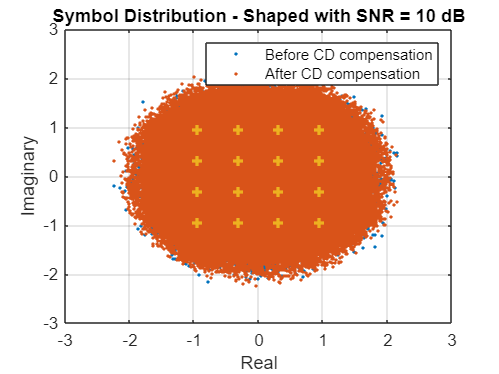


% Matched filtering shaped signals
% Without AWGN
voltageQAM_shaped_CDC_filtered = upfirdn(real(voltageQAM_shaped_CDC),filterResponse, 1, SpS)+1i*upfirdn(imag(voltageQAM_shaped_CDC),filterResponse, 1, SpS);
voltageQAM_shaped_CDC_filtered = voltageQAM_shaped_CDC_filtered(filterSpan+1:end-filterSpan);

% WITH AWGN
clear voltageQAM_shaped_AWGN_CDC_filtered
for i=1:length(SNRb_dB)
    voltageQAM_shaped_AWGN_CDC_filtered(:,i) = upfirdn(real(voltageQAM_shaped_AWGN_CDC(:,i)),filterResponse, 1, SpS)+1i*upfirdn(imag(voltageQAM_shaped_AWGN_CDC(:,i)),filterResponse, 1, SpS);
end

voltageQAM_shaped_AWGN_CDC_filtered = voltageQAM_shaped_AWGN_CDC_filtered(filterSpan+1:end-filterSpan,:);

% Visualising constellation before and after CD compensation
% plot(voltageQAM_CD_I(:,1)+1i*voltageQAM_CD_Q(:,1), '.');
% hold on
% plot(voltageQAM_CDC, '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution - Unshaped without AWGN")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD compensation", "After CD compensation")
% grid on
% hold off
% 
% plot(voltageQAM_shaped_CD_I(:,1)+1i*voltageQAM_shaped_CD_Q(:,1), '.');
% hold on
% plot(voltageQAM_shaped_CDC, '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution - Shaped without AWGN")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD compensation", "After CD compensation")
% grid on
% hold off

% plot(voltageQAM_CD_I(:,1)+1i*voltageQAM_CD_Q(:,1), '.');
% hold on
% plot(voltageQAM_AWGN_CDC(:,end), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution - Unshaped with SNR = 10 dB")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD compensation", "After CD compensation")
% grid on
% hold off

plot(voltageQAM_shaped_CD_I(:,1)+1i*voltageQAM_shaped_CD_Q(:,1), '.');
hold on
plot(voltageQAM_shaped_AWGN_CDC_filtered(:,end), '.');
plot(sourceSymbolsQAM, '+', LineWidth=2);
title("Symbol Distribution - Shaped with SNR = 10 dB")
xlabel("Real")
ylabel("Imaginary")
legend("Before CD compensation", "After CD compensation")
grid on
hold off


% plot(voltageQAM_AWGN_CDC(:,1,1), '.');
% hold on
% plot(voltageQAM_AWGN_CDC(:,1,3), '.');
% plot(voltageQAM_AWGN_CDC(:,1,5), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution with AWGN")
% xlabel("Real")
% ylabel("Imaginary")
% grid on
% hold off

% New Debugging CD compensation

% Without AWGN
% voltageQAM_CDC_debug = voltageQAM_CDC(1:SpS:end); voltageQAM_CDC_debug(2:2:end) = -conj(voltageQAM_CDC_debug(2:2:end));
% IntsQAM_CDC = qamdemod(voltageQAM_CDC_debug, 16, UnitAveragePower=true);
% BitsQAM_CDC = int2bit(IntsQAM_CDC, 4);
% [~, BERQAM_CDC] = biterr(BitsQAM_CDC, sourceBitsQAM)
% 
% voltageQAM_shaped_CDC_debug = voltageQAM_shaped_CDC_filtered;
% voltageQAM_shaped_CDC_debug(2:2:end) = -conj(voltageQAM_shaped_CDC_debug(2:2:end));
% IntsQAM_shaped_CDC = qamdemod(voltageQAM_shaped_CDC_debug, 16, UnitAveragePower=true);
% BitsQAM_shaped_CDC = int2bit(IntsQAM_shaped_CDC, 4);
% [~, BERQAM_shaped_CDC] = biterr(BitsQAM_shaped_CDC, sourceBitsQAM)
% 
% % With AWGN
% % BERQAM_AWGN_CDC = zeros(1,length(SNRb_dB)); BERQAM_shaped_AWGN_CDC = zeros(1,length(SNRb_dB));
% % voltageQAM_AWGN_CDC_debug = voltageQAM_AWGN_CDC(1:SpS:end,:); voltageQAM_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQAM_AWGN_CDC_debug(2:2:end,:)); 
% 
% voltageQAM_shaped_AWGN_CDC_debug = voltageQAM_shaped_AWGN_CDC_filtered;
% voltageQAM_shaped_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQAM_shaped_AWGN_CDC_debug(2:2:end,:)); 
%     
% for i=1:length(SNRb_dB)
% %     IntsQAM_AWGN_CDC_debug = qamdemod(voltageQAM_AWGN_CDC_debug(:,i), 16, UnitAveragePower=true);
% %     BitsQAM_AWGN_CDC_debug = int2bit(IntsQAM_AWGN_CDC_debug, 4);
% %     [~, BERQAM_AWGN_CDC(1,i)] = biterr(BitsQAM_AWGN_CDC_debug, sourceBitsQAM);
% 
%     IntsQAM_shaped_AWGN_CDC_debug = qamdemod(voltageQAM_shaped_AWGN_CDC_debug(:,i), 16, UnitAveragePower=true);
%     BitsQAM_shaped_AWGN_CDC_debug = int2bit(IntsQAM_shaped_AWGN_CDC_debug, 4);
%     [~, BERQAM_shaped_AWGN_CDC(1,i)] = biterr(BitsQAM_shaped_AWGN_CDC_debug, sourceBitsQAM);
% end
% 
% semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
% hold on
% semilogy(SNRb_dB, BERQAM_AWGN_CDC, 'o');
% semilogy(SNRb_dB, BERQAM_shaped_AWGN_CDC, '+');
% title("BER vs. SNR");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

% Old Debugging CD compensation 

% Without AWGN
% voltageQAM_CDC_debug = voltageQAM_CDC(1:SpS:end); voltageQAM_CDC_debug(2:2:end) = -conj(voltageQAM_CDC_debug(2:2:end));
% IntsQAM_CDC = qamdemod(voltageQAM_CDC_debug, 16, UnitAveragePower=true);
% BitsQAM_CDC = int2bit(IntsQAM_CDC, 4);
% [~, BERQAM_CDC] = biterr(BitsQAM_CDC, sourceBitsQAM)
% 
% voltageQAM_shaped_CDC_debug = upfirdn(voltageQAM_shaped_CDC, filterResponse, 1, SpS); voltageQAM_shaped_CDC_debug = voltageQAM_shaped_CDC_debug(filterSpan+1:end-filterSpan);
% voltageQAM_shaped_CDC_debug(2:2:end) = -conj(voltageQAM_shaped_CDC_debug(2:2:end));
% IntsQAM_shaped_CDC = qamdemod(voltageQAM_shaped_CDC_debug, 16, UnitAveragePower=true);
% BitsQAM_shaped_CDC = int2bit(IntsQAM_shaped_CDC, 4);
% [~, BERQAM_shaped_CDC] = biterr(BitsQAM_shaped_CDC, sourceBitsQAM)
% 
% % With AWGN
% BERQAM_AWGN_CDC = zeros(1,length(SNRb_dB)); BERQAM_shaped_AWGN_CDC = zeros(1,length(SNRb_dB));
% voltageQAM_AWGN_CDC_debug = voltageQAM_AWGN_CDC(1:SpS:end,:); voltageQAM_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQAM_AWGN_CDC_debug(2:2:end,:)); 
% 
% clear voltageQAM_shaped_AWGN_CDC_debug
% for i=1:length(SNRb_dB)
%     voltageQAM_shaped_AWGN_CDC_debug(:,i) = upfirdn(real(voltageQAM_shaped_AWGN_CDC(:,i)), filterResponse, 1, SpS); 
%     voltageQAM_shaped_AWGN_CDC_debug(:,i) = voltageQAM_shaped_AWGN_CDC_debug(:,i) + 1i*upfirdn(imag(voltageQAM_shaped_AWGN_CDC(:,i)), filterResponse, 1, SpS); 
% end
% 
% voltageQAM_shaped_AWGN_CDC_debug = voltageQAM_shaped_AWGN_CDC_debug(filterSpan+1:end-filterSpan,:);
% voltageQAM_shaped_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQAM_shaped_AWGN_CDC_debug(2:2:end,:)); 
%     
% for i=1:length(SNRb_dB)
%     IntsQAM_AWGN_CDC_debug = qamdemod(voltageQAM_AWGN_CDC_debug(:,i), 16, UnitAveragePower=true);
%     BitsQAM_AWGN_CDC_debug = int2bit(IntsQAM_AWGN_CDC_debug, 4);
%     [~, BERQAM_AWGN_CDC(1,i)] = biterr(BitsQAM_AWGN_CDC_debug, sourceBitsQAM);
% 
%     IntsQAM_shaped_AWGN_CDC_debug = qamdemod(voltageQAM_shaped_AWGN_CDC_debug(:,i), 16, UnitAveragePower=true);
%     BitsQAM_shaped_AWGN_CDC_debug = int2bit(IntsQAM_shaped_AWGN_CDC_debug, 4);
%     [~, BERQAM_shaped_AWGN_CDC(1,i)] = biterr(BitsQAM_shaped_AWGN_CDC_debug, sourceBitsQAM);
% end
% 
% semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
% hold on
% semilogy(SNRb_dB, BERQAM_AWGN_CDC, 'o');
% semilogy(SNRb_dB, BERQAM_shaped_AWGN_CDC, '+');
% title("BER vs. SNR");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

### Adaptive Equalziation

% Without channel distortion
NTaps = 5; NRemove = 280000; N1 = 120000; Mu_T = 1.7e-5; Mu_DD = Mu_T; Mu_p=4e-2;
% trainSymbsQAM = codedSymbolsQAM; % trainSymbsQAM(2:2:end) = conj(trainSymbsQAM(2:2:end));
trainSymbsQAM = sourceSymbolsQAM;

% WITHOUT AWGN
% Unshaped
% [equalizedSymbsQAM, pQAM, w11QAM, w12QAM, w21QAM, w22QAM, errQAM] = AdapEqualizerAlamouti(voltageQAM_I(:,1)+1i*voltageQAM_Q(:,1), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QAM'); % Unshaped
% [equalizedSymbsQAM_CD, pQAM_CD, w11QAM_CD, w12QAM_CD, w21QAM_CD, w22QAM_CD, errQAM_CD] = AdapEqualizerAlamouti(voltageQAM_CDC, trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Unshaped + CD

% equalizedSymbsQAM_rot = zeros(NSymb,size(thetaArr,2));
% for i=1:size(thetaArr,2)
%     [equalizedSymbsQAM_rot(:,i),pQAM_rot,w11QAM_rot,w12QAM_rot,w21QAM_rot,w22QAM_rot,errQAM_rot] = AdapEqualizerAlamouti(voltageQAM_rot_I(:,1,i)+1i*voltageQAM_rot_Q(:,1,i), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Unshaped + rotation
% end

% Shaped
% [equalizedSymbsQAM_shaped, pQAM_shaped, w11QAM_shaped, w12QAM_shaped, w21QAM_shaped, w22QAM_shaped, errQAM_shaped] = AdapEqualizerAlamouti(voltageQAM_shaped_I(:,1)+1i*voltageQAM_shaped_Q(:,1), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QAM'); % Shaped

% WITH AWGN
equalizedSymbsQAM_AWGN_CD = zeros(NSymb, size(SNRb_dB,1));
equalizedSymbsQAM_shaped_AWGN_CD = zeros(NSymb, size(SNRb_dB,1));
for i=1:length(SNRb_dB)
%      [equalizedSymbsQAM_AWGN_CD(:,i), pQAM_CD, w11QAM_CD, w12QAM_CD, w21QAM_CD, w22QAM_CD, errQAM_CD] = AdapEqualizerAlamouti(voltageQAM_AWGN_CDC(:,i), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QAM'); % Unshaped + CD
     [equalizedSymbsQAM_shaped_AWGN_CD(:,i), pQAM_shaped_CD, w11QAM_shaped_CD, w12QAM_shaped_CD, w21QAM_shaped_CD, w22QAM_shaped_CD, errQAM_shaped_CD] = AdapEqualizerAlamouti(voltageQAM_shaped_AWGN_CDC_filtered(:,i), trainSymbsQAM, 1, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Shaped + CD
end

% Visualising evolution of filter coefficients
% plot([1:size(pQAM)], w11QAM', '-');
% title("QAM Filter Coefficient Variation - w_{11}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM)], w12QAM', '-');
% title("QAM Filter Coefficient Variation - w_{12}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM)], w21QAM', '-');
% title("QAM Filter Coefficient Variation - w_{21}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM)], w22QAM', '-');
% title("QAM Filter Coefficient Variation - w_{22}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM)], pQAM, '-');
% title("QAM p variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQAM(:,1))], abs(errQAM(:,1)), '-');
% title("QAM Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQAM(:,2))], abs(errQAM(:,2)), '-');
% title("QAM Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQAM_I(:,1)+1i*voltageQAM_Q(:,1), '.');
% hold on
% title("Symbol Distribution")
% plot(equalizedSymbsQAM(1:NRemove), '.');
% plot(equalizedSymbsQAM(NRemove+1:end), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Training", "DD")
% grid on
% hold off


% ----------------------------------------------------------------------------
% With CD added

% Visualising evolution of filter coefficients
plot([1:size(pQAM_shaped_CD)], w11QAM_shaped_CD', '-');

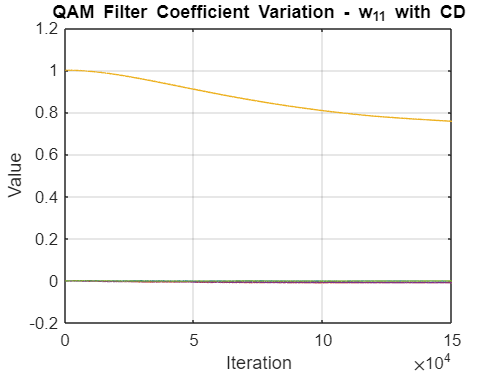

title("QAM Filter Coefficient Variation - w_{11} with CD")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped_CD)], w12QAM_shaped_CD', '-');

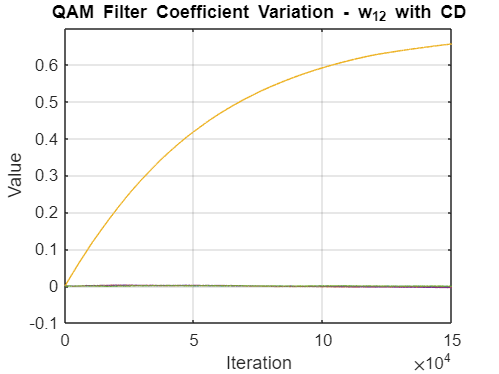

title("QAM Filter Coefficient Variation - w_{12} with CD")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped_CD)], w21QAM_shaped_CD', '-');

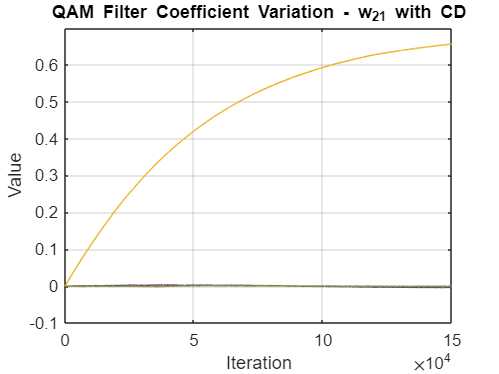

title("QAM Filter Coefficient Variation - w_{21} with CD")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped_CD)], w22QAM_shaped_CD', '-');

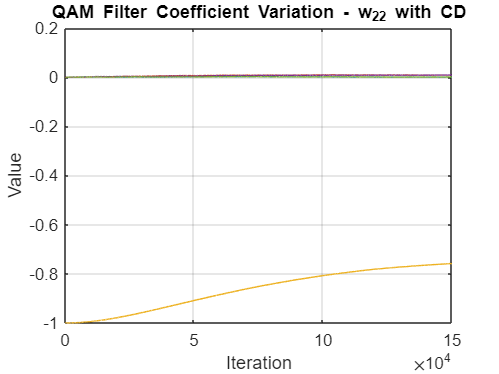

title("QAM Filter Coefficient Variation - w_{22} with CD")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped_CD)], pQAM_shaped_CD, '-');

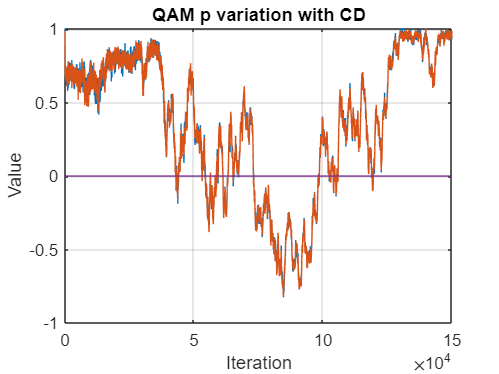

title("QAM p variation with CD")
xlabel("Iteration")
ylabel("Value")
grid on

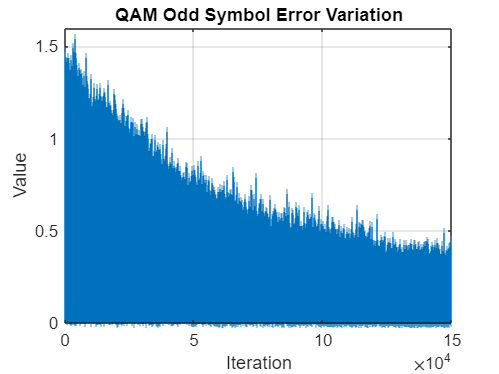


stem([1:size(errQAM_shaped_CD(:,1))], abs(errQAM_shaped_CD(:,1)), '|');
title("QAM Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

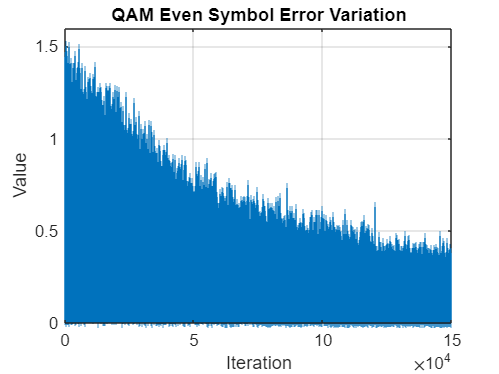


stem([1:size(errQAM_shaped_CD(:,2))], abs(errQAM_shaped_CD(:,2)), '|');
title("QAM Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

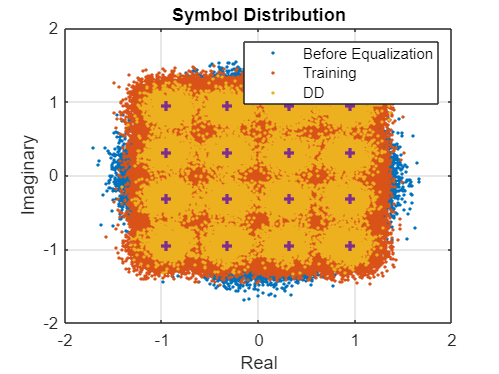


plot(voltageQAM_CDC, '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbsQAM_shaped_AWGN_CD(1:NRemove,end), '.');
plot(equalizedSymbsQAM_shaped_AWGN_CD(NRemove+1:end,end), '.');
plot(sourceSymbolsQAM, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off


% plot(1:NTaps, abs(w11QAM_CD(:,1)), "-o")
% hold on
% plot(1:NTaps, abs(w12QAM_CD(:,1)), "-o")
% plot(1:NTaps, abs(w21QAM_CD(:,1)), "-o")
% plot(1:NTaps, abs(w22QAM_CD(:,1)), "-o")
% xlabel("Tap No.")
% ylabel("Value")
% legend("w_{11}", "w_{12}", "w_{21}", "w_{22}")
% grid on
% hold off


% ----------------------------------------------------------------------------
% With rotation

% Visualising evolution of filter coefficients
% plot([1:size(pQAM_rot)], w11QAM_rot', '-');
% title("QAM Filter Coefficient Variation - w_{11} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_rot)], w12QAM_rot', '-');
% title("QAM Filter Coefficient Variation - w_{12} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_rot)], w21QAM_rot', '-');
% title("QAM Filter Coefficient Variation - w_{21} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_rot)], w22QAM_rot', '-');
% title("QAM Filter Coefficient Variation - w_{22} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_rot)], real(pQAM_rot), '-');
% hold on
% plot([1:size(pQAM_rot)], imag(pQAM_rot), '-');
% title("QAM p variation with rot")
% xlabel("Iteration")
% ylabel("Value")
% legend("Real", "Imaginary")
% grid on
% hold off
% 
% stem([1:size(errQAM_rot(:,1))], abs(errQAM_rot(:,1)), '|');
% title("QAM Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQAM_rot(:,2))], abs(errQAM_rot(:,2)), '|');
% title("QAM Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQAM_rot_I(:,1,end)+1i*voltageQAM_rot_Q(:,1,end), '.', LineWidth=2);
% hold on
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution Before Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Original")
% grid on
% hold off
% 
% plot(equalizedSymbsQAM_rot(1:N1*2,1), '.');
% hold on
% plot(equalizedSymbsQAM_rot(N1*2+1:NRemove,1), '.');
% plot(equalizedSymbsQAM_rot(NRemove+1:end,1), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution During Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Training", "DD", "Final", "Original")
% grid on
% hold off
% 
% plot(equalizedSymbsQAM_rot(1:N1*2,end), '.');
% hold on
% plot(equalizedSymbsQAM_rot(N1*2+1:NRemove,end), '.');
% plot(equalizedSymbsQAM_rot(NRemove:end, end), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution During Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Training", "DD", "Final", "Original")
% grid on
% hold off


% ----------------------------------------------------------------------------
% Shaped

% Visualising evolution of filter coefficients
% plot([1:size(pQAM_shaped)], w11QAM_shaped', '-');
% title("QAM Filter Coefficient Variation - w_{11} shaped")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_shaped)], w12QAM_shaped', '-');
% title("QAM Filter Coefficient Variation - w_{12} shaped")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_shaped)], w21QAM_shaped', '-');
% title("QAM Filter Coefficient Variation - w_{21} shaped")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_shaped)], w22QAM_shaped', '-');
% title("QAM Filter Coefficient Variation - w_{22} shaped")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQAM_shaped)], real(pQAM_shaped), '-');
% hold on
% plot([1:size(pQAM_shaped)], imag(pQAM_shaped), '-');
% title("QAM p variation with shaped")
% xlabel("Iteration")
% ylabel("Value")
% legend("Real", "Imaginary")
% grid on
% hold off
% 
% stem([1:size(errQAM_shaped(:,1))], abs(errQAM_shaped(:,1)), '-');
% title("QAM Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQAM_shaped(:,2))], abs(errQAM_shaped(:,2)), '-');
% title("QAM Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQAM_shaped_I(:,1,end)+1i*voltageQAM_shaped_Q(:,1,end), '.', LineWidth=2);
% hold on
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution Before Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Original")
% grid on
% hold off
% 
% plot(equalizedSymbsQAM_shaped(1:N1/2,1), '.');
% hold on
% plot(equalizedSymbsQAM_shaped(N1/2+1:NRemove,1), '.');
% plot(equalizedSymbsQAM_shaped(NRemove+1:end,1), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution During Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Training", "DD", "Final", "Original")
% grid on
% hold off
% 
% plot(equalizedSymbsQAM_shaped(1:N1/2,end), '.');
% hold on
% plot(equalizedSymbsQAM_shaped(N1/2+1:NRemove,end), '.');
% plot(equalizedSymbsQAM_shaped(NRemove+1:end,end), '.');
% plot(sourceSymbolsQAM, '+', LineWidth=2);
% title("Symbol Distribution During Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Training", "DD", "Final", "Original")
% grid on
% hold off


## Receiver

### Decoding and Decision

% Without MIMO equalization:
% Unshaped
% testSymbolsQAM = voltageQAM_I(:,1) + 1i*voltageQAM_Q(:,1);
% testSymbolsQAM(2:2:end,1) = -1*conj(testSymbolsQAM(2:2:end,1));
% testIntsQAM = qamdemod(testSymbolsQAM, 16, UnitAveragePower=true);
% testBitsQAM = int2bit(testIntsQAM, 4);
% biterr(testBitsQAM, sourceBitsQAM)

% Shaped
% testSymbolsQAM_shaped = voltageQAM_shaped_I(:,1) + 1i*voltageQAM_shaped_Q(:,1);
% testSymbolsQAM_shaped(2:2:end,1) = -1*conj(testSymbolsQAM_shaped(2:2:end,1));
% testIntsQAM_shaped = qamdemod(testSymbolsQAM_shaped, 16, UnitAveragePower=true);
% testBitsQAM_shaped = int2bit(testIntsQAM_shaped, 4);
% biterr(testBitsQAM_shaped, sourceBitsQAM)

% -------------------------------------------------------------------------------

% With MIMO Eqaulization
% Unshaped
% After Equalization
% equalizedIntsQAM_train = qamdemod(equalizedSymbsQAM(1:N1*2,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_train = int2bit(equalizedIntsQAM_train, 4);
% [~, BERQAM_train] = biterr(equalizedBitsQAM_train, sourceBitsQAM(1:N1*8))
% 
% equalizedIntsQAM_dd = qamdemod(equalizedSymbsQAM(N1*2+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_dd = int2bit(equalizedIntsQAM_dd, 4);
% [~, BERQAM_dd] = biterr(equalizedBitsQAM_dd, sourceBitsQAM(N1*8+1:end))
% 
% equalizedIntsQAM = qamdemod(equalizedSymbsQAM(NRemove+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM = int2bit(equalizedIntsQAM, 4);
% [~, BERQAM] = biterr(equalizedBitsQAM, sourceBitsQAM(NRemove*2+1:end))

% ----------------------

% Unshaped + CD
% Before equalization
% distortedSymbsQAM = voltageQAM_CD_I(1:SpS:end,1)+1i*voltageQAM_CD_Q(1:SpS:end,1);
% distortedSymbsQAM(2:2:end,1) = -1*conj(distortedSymbsQAM(2:2:end,1));
% IntsQAM_CD = qamdemod(distortedSymbsQAM, 16, UnitAveragePower=true);
% BitsQAM_CD = int2bit(IntsQAM_CD, 4);
% [~, BERQAM_CD_before] = biterr(BitsQAM_CD, sourceBitsQAM)
% 
% % After equalization
% equalizedIntsQAM_CD_train = qamdemod(equalizedSymbsQAM_CD(1:N1*2,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_CD_train = int2bit(equalizedIntsQAM_CD_train, 4);
% [~, BERQAM_CD_train] = biterr(equalizedBitsQAM_CD_train, sourceBitsQAM(1:N1*8))
% 
% equalizedIntsQAM_CD_dd = qamdemod(equalizedSymbsQAM_CD(N1*2+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_CD_dd = int2bit(equalizedIntsQAM_CD_dd, 4);
% [~, BERQAM_CD_dd] = biterr(equalizedBitsQAM_CD_dd, sourceBitsQAM(N1*8+1:end))
% 
% equalizedIntsQAM_CD = qamdemod(equalizedSymbsQAM_CD(NRemove+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_CD = int2bit(equalizedIntsQAM_CD, 4);
% [~, BERQAM_CD] = biterr(equalizedBitsQAM_CD, sourceBitsQAM(NRemove*2+1:end))


% ----------------------

% Unshaped + rotation
% Before equalization
% distortedSymbsQAM = voltageQAM_rot_I(1:SpS:end,1, end)+1i*voltageQAM_rot_Q(1:SpS:end,1, end);
% distortedSymbsQAM(2:2:end,1) = -1*conj(distortedSymbsQAM(2:2:end,1));
% IntsQAM_rot = qamdemod(distortedSymbsQAM, 16, UnitAveragePower=true);
% BitsQAM_rot = int2bit(IntsQAM_rot, 4);
% [~, BERQAM_rot_before] = biterr(BitsQAM_rot, sourceBitsQAM)
% 
% % After equalization
% equalizedIntsQAM_rot_train = qamdemod(equalizedSymbsQAM_rot(1:N1*2,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_rot_train = int2bit(equalizedIntsQAM_rot_train, 4);
% [~, BERQAM_rot_train] = biterr(equalizedBitsQAM_rot_train, sourceBitsQAM(1:N1*8))

% equalizedIntsQAM_rot_dd = qamdemod(equalizedSymbsQAM_rot(N1*2+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_rot_dd = int2bit(equalizedIntsQAM_rot_dd, 4);
% [~, BERQAM_rot_dd] = biterr(equalizedBitsQAM_rot_dd, sourceBitsQAM(N1*8+1:end))

% equalizedIntsQAM_rot = qamdemod(equalizedSymbsQAM_rot(NRemove+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_rot = int2bit(equalizedIntsQAM_rot, 4);
% [~, BERQAM_rot] = biterr(equalizedBitsQAM_rot, sourceBitsQAM(NRemove*4+1:end))


% ---------------------------------------------------------------------------------------

% Shaped
% After equalization
% equalizedIntsQAM_shaped_train = qamdemod(equalizedSymbsQAM_shaped(1:N1*2,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_shaped_train = int2bit(equalizedIntsQAM_shaped_train, 4);
% [~, BERQAM_shaped_train] = biterr(equalizedBitsQAM_shaped_train, sourceBitsQAM(1:N1*8))
% 
% equalizedIntsQAM_shaped_dd = qamdemod(equalizedSymbsQAM_shaped(N1*2+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_shaped_dd = int2bit(equalizedIntsQAM_shaped_dd, 4);
% [~, BERQAM_shaped_dd] = biterr(equalizedBitsQAM_shaped_dd, sourceBitsQAM(N1*8+1:end))
% 
% equalizedIntsQAM_shaped = qamdemod(equalizedSymbsQAM_shaped(NRemove+1:end,:), 16, UnitAveragePower=true);
% equalizedBitsQAM_shaped = int2bit(equalizedIntsQAM_shaped, 4);
% [~, BERQAM_shaped] = biterr(equalizedBitsQAM_shaped, sourceBitsQAM(NRemove*2+1:end))

### BER vs SNR

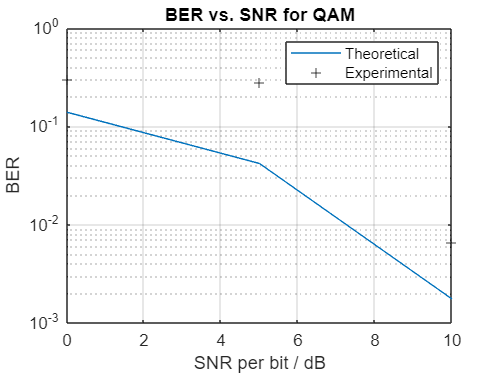

BERQAM_AWGN_CD = zeros(1, length(SNRb_dB)); BERQAM_shaped_AWGN_CD = zeros(1, length(SNRb_dB));

for i=1:length(SNRb_dB)
%     equalizedIntsQAM_AWGN_CD = qamdemod(equalizedSymbsQAM_AWGN_CD(NRemove+1:end,i), 16, UnitAveragePower=true);
%     equalizedBitsQAM_AWGN_CD = int2bit(equalizedIntsQAM_AWGN_CD, 4);
%     [~, BERQAM_AWGN_CD(1,i)] = biterr(equalizedBitsQAM_AWGN_CD, sourceBitsQAM(NRemove*2+1:end));

    equalizedIntsQAM_shaped_AWGN_CD = qamdemod(equalizedSymbsQAM_shaped_AWGN_CD(NRemove+1:end,i), 16, UnitAveragePower=true);
    equalizedBitsQAM_shaped_AWGN_CD = int2bit(equalizedIntsQAM_shaped_AWGN_CD, 4);
    [~, BERQAM_shaped_AWGN_CD(1,i)] = biterr(equalizedBitsQAM_shaped_AWGN_CD, sourceBitsQAM(NRemove*4+1:end));

end

semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
hold on
% semilogy(SNRb_dB, BERQAM_AWGN_CD', '*');
semilogy(SNRb_dB, BERQAM_shaped_AWGN_CD', 'k+');
title("BER vs. SNR for QAM");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Experimental");
grid on
hold off